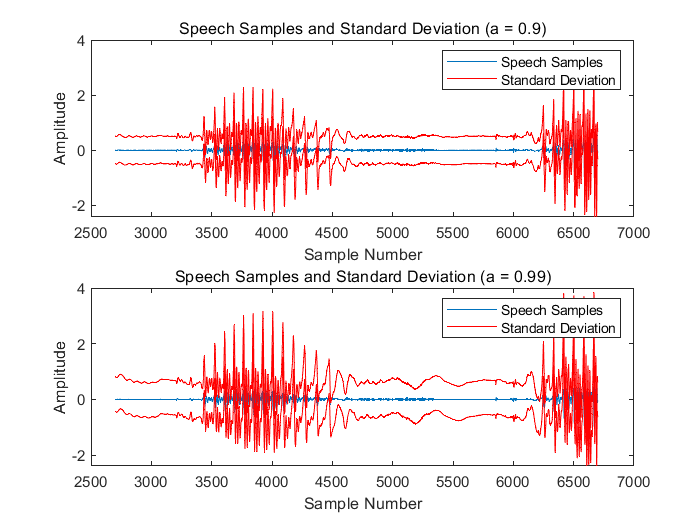

% Load speech file
[x, Fs] = audioread('s5.wav');

% Define filter coefficients
a1 = 0.9;
a2 = 0.99;

% Apply IIR filter to speech signal
y1 = filter(1, [1, -a1], x);
y2 = filter(1, [1, -a2], x);

% Calculate standard deviation of filtered signal
o1 = std(y1);
o2 = std(y2);

% Define sample range
n = 2700:6700;

% Plot speech samples and superimposed standard deviation samples
figure;
subplot(2,1,1);
plot(n, x(n));
hold on;
plot(n, y1(n) + o1, 'r');
plot(n, y1(n) - o1, 'r');
title('Speech Samples and Standard Deviation (a = 0.9)');
xlabel('Sample Number');
ylabel('Amplitude');
legend('Speech Samples', 'Standard Deviation');

subplot(2,1,2);
plot(n, x(n));
hold on;
plot(n, y2(n) + o2, 'r');
plot(n, y2(n) - o2, 'r');
title('Speech Samples and Standard Deviation (a = 0.99)');
xlabel('Sample Number');
ylabel('Amplitude');
legend('Speech Samples', 'Standard Deviation');